clear; 
clc;

% Create pseudo population by combining aligned data from all subjects.
% Separate dataset by tastant.
% S, C, N, and Q refer to sucrose, NaCl, citric acid, and quinine, but are
% also used to label tastants in mixture and sucrose exp.
load("phasic_palatability.mat") % Change this to analyze a different dataset
[S_aligned, N_aligned, C_aligned, Q_aligned] = unpack_dataset(phasic_palatability.data_by_subject);

% Trial number per trial type
 trial_num = 12;
 nostim_trials = 1:12;
 stim_trials = 13:24;
 trials_used = [nostim_trials, stim_trials];
 
% Tranform aligned traces as change from baseline. Baseline is from -3 to 0 (frame 21 to 50)
% This excludes the stimulation period
%BL = 21:50; %21:50 previously
BL = 11:40;
S_aligned_df = S_aligned - mean(S_aligned(:, :, BL), 3);
N_aligned_df = N_aligned - mean(N_aligned(:, :, BL), 3);
C_aligned_df = C_aligned - mean(C_aligned(:, :, BL), 3);
Q_aligned_df = Q_aligned - mean(Q_aligned(:, :, BL), 3);

% Take 0-5s of the response (52:101). Convert data to 10 time bins of 500 ms
S_aligned_binned = bin_data(S_aligned_df(:,:, 52:101), 10);
N_aligned_binned = bin_data(N_aligned_df(:,:, 52:101), 10);
C_aligned_binned = bin_data(C_aligned_df(:,:, 52:101), 10);
Q_aligned_binned = bin_data(Q_aligned_df(:,:, 52:101), 10);

% Identify stimulus-discriminative and LC-modulated neurons (Figure 2A, 4A, 5A, 7D).


% "Taste resposive" neurons have consistent responses to tastant delivery,
% but their responses may not distinguish among tastants.

% Find the number of neurons responsive to each taste
% Use p-value threshhold of 0.005
threshold = 1;
alpha = 0.001;

% Sweet
S_nostim_responsive = test_responsive(S_aligned_binned(:, nostim_trials, :), alpha, threshold);
S_stim_responsive = test_responsive(S_aligned_binned(:, stim_trials, :), alpha, threshold);

% Salty
N_nostim_responsive = test_responsive(N_aligned_binned(:, nostim_trials, :), alpha, threshold);
N_stim_responsive = test_responsive(N_aligned_binned(:, stim_trials, :), alpha, threshold);

% Sour
C_nostim_responsive = test_responsive(C_aligned_binned(:, nostim_trials, :), alpha, threshold);
C_stim_responsive = test_responsive(C_aligned_binned(:, stim_trials, :), alpha, threshold);

% Bitter
Q_nostim_responsive = test_responsive(Q_aligned_binned(:, nostim_trials, :), alpha, threshold);
Q_stim_responsive = test_responsive(Q_aligned_binned(:, stim_trials, :), alpha, threshold);

% Combine responsive neurons across tastants
taste_responsive = find(S_nostim_responsive|S_stim_responsive| ...
                        N_nostim_responsive|N_stim_responsive| ...
                        C_nostim_responsive|C_stim_responsive| ...
                        Q_nostim_responsive|Q_stim_responsive);


% Find the number of taste-discrimantive neurons
% No-stim trials
[main_nostim, interact_nostim, significant_nostim] = test_discriminative(S_aligned_binned(:, nostim_trials, :), ...
    N_aligned_binned(:, nostim_trials, :), ...
    C_aligned_binned(:, nostim_trials, :), ...
    Q_aligned_binned(:, nostim_trials, :));

% Stim trials
[main_stim, interact_stim, significant_stim] = test_discriminative(S_aligned_binned(:, stim_trials, :), ...
    N_aligned_binned(:, stim_trials, :), ...
    C_aligned_binned(:, stim_trials, :), ...
    Q_aligned_binned(:, stim_trials, :));

discriminative_neurons = union(significant_nostim,significant_stim);


% Identify cell-taste pairs that are significantly modulated by stimulation
[main_S, interact_S, sig_S] = test_modulated(S_aligned_binned(:,trials_used,:), 12);
[main_N, interact_N, sig_N] = test_modulated(N_aligned_binned(:,trials_used,:), 12);
[main_C, interact_C, sig_C] = test_modulated(C_aligned_binned(:,trials_used,:), 12);
[main_Q, interact_Q, sig_Q] = test_modulated(Q_aligned_binned(:,trials_used,:), 12);


sig_mod = union(union(sig_S, sig_C), union(sig_Q, sig_N))

sig_mod =      1    14    19    20    38    39    49    60    64    66    73    74    75    76    77    91    93    95    97   110   114   121   122   128   133   139   140   155   156   158   161   166   169   175   187   188   192   193   194   198   200   203   205   212   215   216   217   228   229   238


sig_mod_D = intersect(sig_mod, discriminative_neurons)

sig_mod_D =     14    19    39    49    60    64    66    74    75    76    77    91   110   114   121   122   128   133   140   155   158   166   175   187   188   192   193   198   200   203   215   216   217   228   229   243   253   261   266   271   273   284   295   301   346   347   349   351   364   367



% The intersection of taste-discriminative and taste-responsive is referred
% to as stimulus-discriminative in the paper (sig_mod_DR).
D_and_R = intersect(discriminative_neurons, taste_responsive)'

D_and_R =      4     5     9    11    14    18    19    21    23    25    26    27    29    34    35    36    39    40    41    42    43    44    45    46    48    49    50    55    60    62    63    64    66    67    71    74    75    76    77    79    80    81    85    86    88    89    91    92    94    99


% LC-modulated, stimulus-discriminative neurons
sig_mod_DR = intersect(sig_mod_D, taste_responsive)'

sig_mod_DR =     14    19    39    49    60    64    66    74    75    76    77    91   110   114   121   122   128   133   140   155   158   166   175   188   192   198   200   203   215   217   229   243   261   266   271   273   284   301   346   347   349   351   364   367   368   376   377   404   423   435




% Define which cell list to use for analysis
% e.g., sigmod_DR, D_and_R, pos_mod, neg_mod
cell_list_for_analysis = sig_mod_DR;

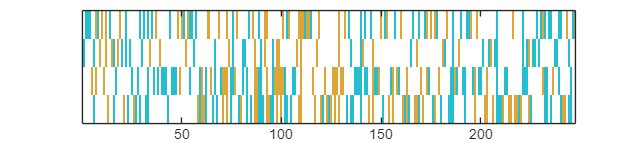

% Summarize LC-induced enhacement and suppression across cell-taste pairs
% (Figure 2C, 4B, 5B)


% Creat a matrix that represent significantly modulated cell-taste
% pairs as 1 and others as 0.
cell_list = 1:size(S_aligned,1);
sig_S_bool = ismember(cell_list, sig_S);
sig_N_bool = ismember(cell_list, sig_N);
sig_C_bool = ismember(cell_list, sig_C);
sig_Q_bool = ismember(cell_list, sig_Q);

sig_bool = [sig_S_bool; sig_N_bool; sig_C_bool; sig_Q_bool];
sig_bool_DR = sig_bool(:, cell_list_for_analysis);


% Combine trial average data
% These trial mean matrices are also used for correlation analysis
S_binned_trial_means_nostim = squeeze(mean(S_binned_sig_nostim, 2)); 
N_binned_trial_means_nostim = squeeze(mean(N_binned_sig_nostim, 2));
C_binned_trial_means_nostim = squeeze(mean(C_binned_sig_nostim, 2));
Q_binned_trial_means_nostim = squeeze(mean(Q_binned_sig_nostim, 2));

combined_trial_means_nostim = cat(3, S_binned_trial_means_nostim,...
                                N_binned_trial_means_nostim,...
                                C_binned_trial_means_nostim,...
                                Q_binned_trial_means_nostim);

S_binned_trial_means_stim = squeeze(mean(S_binned_sig_stim, 2)); 
N_binned_trial_means_stim = squeeze(mean(N_binned_sig_stim, 2));
C_binned_trial_means_stim = squeeze(mean(C_binned_sig_stim, 2));
Q_binned_trial_means_stim = squeeze(mean(Q_binned_sig_stim, 2));

combined_trial_means_stim = cat(3, S_binned_trial_means_stim,...
                                N_binned_trial_means_stim,...
                                C_binned_trial_means_stim,...
                                Q_binned_trial_means_stim);


% Describe the direction of modulation (+1 for enhanced, -1 for suppressed, 0 for no significance)
mod_direction = zeros(length(cell_list_for_analysis), 4);    % Increase or decrease in dF

for cell_id = 1:length(cell_list_for_analysis)
    for taste = 1:4
        delta_response = sum(squeeze(combined_trial_means_stim(cell_id, :, taste)) ... 
                       - squeeze(combined_trial_means_nostim(cell_id, :, taste)));
        if delta_response > 1
            mod_direction(cell_id, taste) = 1;
        else
            mod_direction(cell_id, taste) = -1;
        end
    end
end

mod_direction = mod_direction' .* sig_bool_DR; % This converts all the non-significant cell-taste pairs to 0.
mod_direction_sorted = sortrows(mod_direction', [1 2 3 4], "descend")';


% Visualize modulation directions
cmap = [0.1373, 0.7451, 0.8196;
        1 1 1;
        0.8706, 0.6471, 0.2196];
figure;
imagesc(mod_direction); colormap(cmap);
set(gca, "YTick", [], "LineWidth", 1)
set(gcf, "Position", [300 300 1600 360])

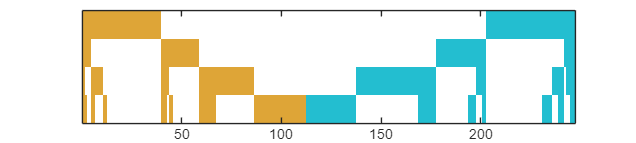


figure;
imagesc(mod_direction_sorted); colormap(cmap);
set(gca, "YTick", [],  "LineWidth", 1)
set(gcf, "Position", [300 300 1600 360])



% Get indices of cells with only positive and negative shift
pos_bool = any(mod_direction == 1, 1) & ~ any(mod_direction == -1, 1);
pos_idx = find(pos_bool);
pos_mod = sig_mod_DR(pos_idx); % LC-enhanced neurons

neg_bool = any(mod_direction == -1, 1) & ~ any(mod_direction == 1, 1);
neg_idx = find(neg_bool);
neg_mod = sig_mod_DR(neg_idx); % LC-suppressed neurons

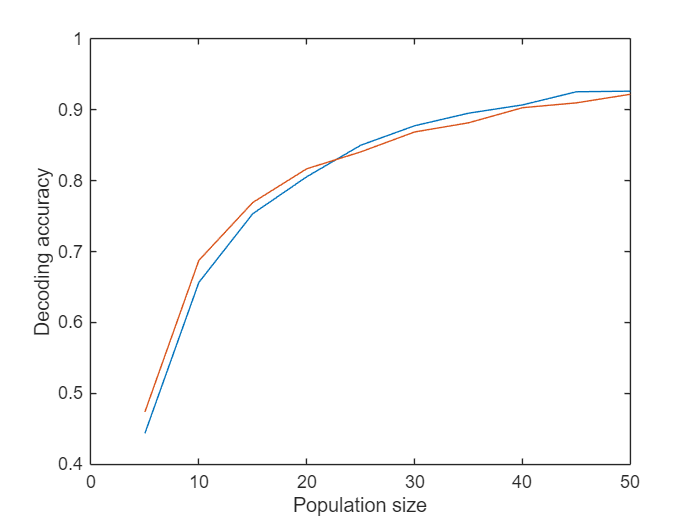

% Population decoding (Figure 3A, 4C, 5C, S5AD, S6AD, S7AD, S9)


% Regroup data into two matrices for stim and no-stim conditions.
% Four tastants are combined in each matrix.

S_binned_sig_nostim = S_aligned_binned(cell_list_for_analysis, nostim_trials, :);
N_binned_sig_nostim = N_aligned_binned(cell_list_for_analysis, nostim_trials, :);
C_binned_sig_nostim = C_aligned_binned(cell_list_for_analysis, nostim_trials, :);
Q_binned_sig_nostim = Q_aligned_binned(cell_list_for_analysis, nostim_trials, :);

combined_binned_sig_nostim = cat(2,S_binned_sig_nostim, N_binned_sig_nostim, C_binned_sig_nostim, Q_binned_sig_nostim);

S_binned_sig_stim = S_aligned_binned(cell_list_for_analysis, stim_trials, :);
N_binned_sig_stim = N_aligned_binned(cell_list_for_analysis, stim_trials, :);
C_binned_sig_stim = C_aligned_binned(cell_list_for_analysis, stim_trials, :);
Q_binned_sig_stim = Q_aligned_binned(cell_list_for_analysis, stim_trials, :);

combined_binned_sig_stim = cat(2,S_binned_sig_stim, N_binned_sig_stim, C_binned_sig_stim, Q_binned_sig_stim);


% population decoding using all bins of each neuron 
% (may take a few minute to complete.)
pop_sizes = [5, 10, 15, 20, 25, 30, 35, 40, 45, 50];
[pop_decode_accuracy_nostim, confmats_nostim] = decode_pop_sizes(combined_binned_sig_nostim, 6, pop_sizes, 100);
[pop_decode_accuracy_stim, confmats_stim] = decode_pop_sizes(combined_binned_sig_stim, 6, pop_sizes, 100);

% Mean decoding accuracy of each condition
mean_pop_accuracy_nostim = mean(pop_decode_accuracy_nostim, 2);
mean_pop_accuracy_stim = mean(pop_decode_accuracy_stim, 2);

% Plot decoding accuracy against population size
figure;
plot(pop_sizes, mean_pop_accuracy_nostim)
hold on
plot(pop_sizes, mean_pop_accuracy_stim)
hold off

xlabel('Population size')
ylabel('Decoding accuracy')



% permutation test for population decoding accuracy. This block may take
% more than 10 hrs to complete due to the number of permutations performed
n_perms = 1000;
n_boots = 50;
diff_acc_distribution = zeros(length(pop_sizes), n_perms);

for perm = 1:n_perms
    rng(perm, "twister");
    [nostim_perm, stim_perm] = permute_datasets(combined_binned_sig_nostim, combined_binned_sig_stim);
    pop_decode_accuracy_nostim = decode_pop_sizes(nostim_perm, 6, pop_sizes, n_boots);
    pop_decode_accuracy_stim = decode_pop_sizes(stim_perm, 6, pop_sizes, n_boots);

    mean_pop_accuracy_nostim = mean(pop_decode_accuracy_nostim, 2);
    mean_pop_accuracy_stim = mean(pop_decode_accuracy_stim, 2);
    diff_acc_distribution(:, perm) = mean_pop_accuracy_stim - mean_pop_accuracy_nostim;
end

% Calculating p-value for each population size
pop_pvalues = zeros(length(pop_sizes), 1); % p-values
for i = 1:length(pop_sizes)
    null_dist = diff_acc_distribution(i, :);
    acc_diff = pop_acc_diff(i);
    p_val = mean(abs(null_dist) >= abs(acc_diff));
    pop_pvalues(i) = p_val;
end

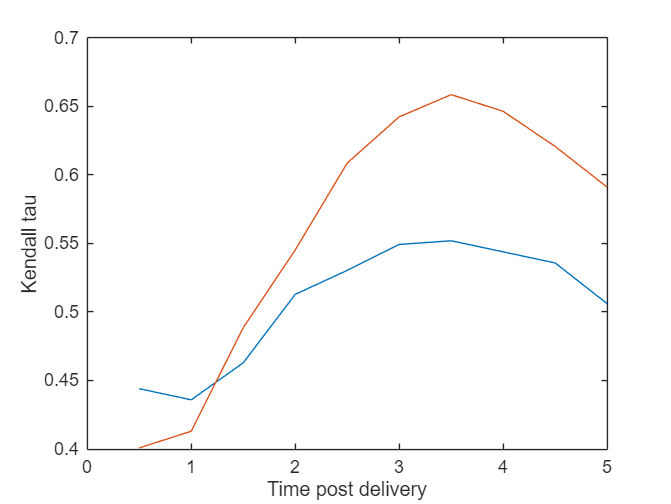

% Response-stimulus correlation (Figure 3B, 4D, 5D, S5AD, S6AD, S7AD, S8D-I, S9)


% Calculate Kendall's correlation
nostim_palatability_corr = palatability_corr(combined_trial_means_nostim);
stim_palatability_corr = palatability_corr(combined_trial_means_stim);
figure;
plot(0.5:0.5:5, mean(nostim_palatability_corr, 2))
hold on
plot(0.5:0.5:5, mean(stim_palatability_corr, 2))
hold off

xlabel('Time post delivery')
ylabel('Kendall tau')

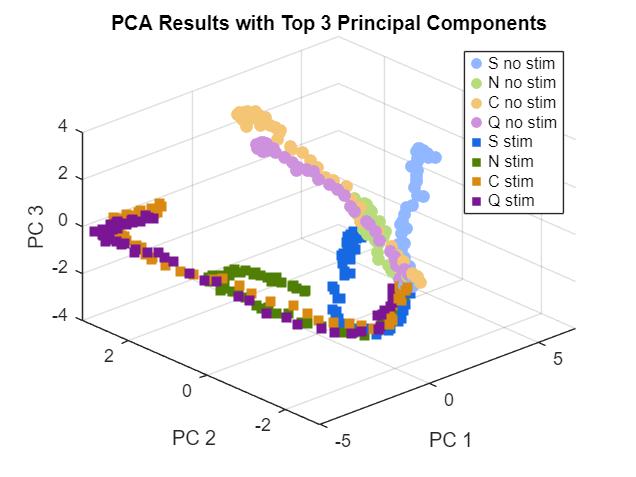

% Step 1 of PCA. Computing PCs from trial-mean data

% Normalized the binned response of each cell by the absolute value of the
%  maximum trial mean response
S_binned_mean_nostim = mean(S_aligned_binned(:, nostim_trials,:), 2);
N_binned_mean_nostim = mean(N_aligned_binned(:, nostim_trials,:), 2);
C_binned_mean_nostim = mean(C_aligned_binned(:, nostim_trials,:), 2);
Q_binned_mean_nostim = mean(Q_aligned_binned(:, nostim_trials,:), 2);

S_binned_mean_stim = mean(S_aligned_binned(:, stim_trials,:), 2);
N_binned_mean_stim = mean(N_aligned_binned(:, stim_trials,:), 2);
C_binned_mean_stim = mean(C_aligned_binned(:, stim_trials,:), 2);
Q_binned_mean_stim = mean(Q_aligned_binned(:, stim_trials,:), 2);
combined_binned = cat(2,S_binned_mean_nostim, N_binned_mean_nostim, C_binned_mean_nostim, Q_binned_mean_nostim, ...
    S_binned_mean_stim, N_binned_mean_stim, C_binned_mean_stim, Q_binned_mean_stim);
combined_binned_abs = abs(combined_binned);
max_val = max(combined_binned_abs, [], [2,3]);  % Normalization factor

% Prepare design matrix for PCA analysis

window = 41:100;

S_nostim = S_aligned_df(cell_list_for_analysis, nostim_trials, window);
N_nostim = N_aligned_df(cell_list_for_analysis, nostim_trials, window);
C_nostim = C_aligned_df(cell_list_for_analysis, nostim_trials, window);
Q_nostim = Q_aligned_df(cell_list_for_analysis, nostim_trials, window);

S_stim = S_aligned_df(cell_list_for_analysis, stim_trials, window);
N_stim = N_aligned_df(cell_list_for_analysis, stim_trials, window);
C_stim = C_aligned_df(cell_list_for_analysis, stim_trials, window);
Q_stim = Q_aligned_df(cell_list_for_analysis, stim_trials, window);

% trial means, transposed (bins x cells)
S_nostim_trial_mean = squeeze(mean(S_nostim, 2))';
N_nostim_trial_mean = squeeze(mean(N_nostim, 2))';
C_nostim_trial_mean = squeeze(mean(C_nostim, 2))';
Q_nostim_trial_mean = squeeze(mean(Q_nostim, 2))';

S_stim_trial_mean = squeeze(mean(S_stim, 2))';
N_stim_trial_mean = squeeze(mean(N_stim, 2))';
C_stim_trial_mean = squeeze(mean(C_stim, 2))';
Q_stim_trial_mean = squeeze(mean(Q_stim, 2))';

trial_mean_design_mat = cat(1, S_nostim_trial_mean, ...
                                N_nostim_trial_mean, ...
                                C_nostim_trial_mean, ...
                                Q_nostim_trial_mean, ...
                                S_stim_trial_mean, ...
                                N_stim_trial_mean, ...
                                C_stim_trial_mean, ...
                                Q_stim_trial_mean);

% Normalized trial-mean design matrix for PCA analysis
trial_mean_design_mat_norm = trial_mean_design_mat ./ max_val(cell_list_for_analysis)';


% Perform PCA
[coeff, score, ~, ~, explained] = pca(trial_mean_design_mat_norm);


% Visualizing the population dynamics of each trial type
colors = [
    "#90b7ff"; % Light blue
    "#b7dc7b"; % Light green
    "#f3c574"; % Light brown
    "#ce91de"; % Light purple
    "#1669e2";       % Dark blue
    "#4f7f04";       % Dark green
    "#da8910"; % Dark brown
    "#7a1694"  % Dark purple
];

shapes = ["o", "o", "o", "o", "square", "square", "square", "square"];

timepoint_per_trial_type = length(window);

% Plot the top 3 principal components
figure;
hold on;
for i = 1:8
    % Select data for the i-th class (251 observations per class)
    class_data = score((i-1)*timepoint_per_trial_type+1:i*timepoint_per_trial_type, 1:3);
    %class_data = score((i-1)*50+1:i*50, 1:3);
    % % Plot the data points for the i-th class with specified color
    scatter3(class_data(:, 1), class_data(:, 2), class_data(:, 3), 50, ...
             'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'none', ...
             'DisplayName', sprintf('Class %d', i), "Marker", shapes(i));

end

% Label the axes
xlabel('PC 1');
ylabel('PC 2');
zlabel('PC 3');

% Add legend and title
legend({'S no stim', 'N no stim', 'C no stim', 'Q no stim', ...
        'S stim', 'N stim', 'C stim', 'Q stim'}, 'Location', 'best');
title('PCA Results with Top 3 Principal Components');
grid on;
hold off;

view(3);

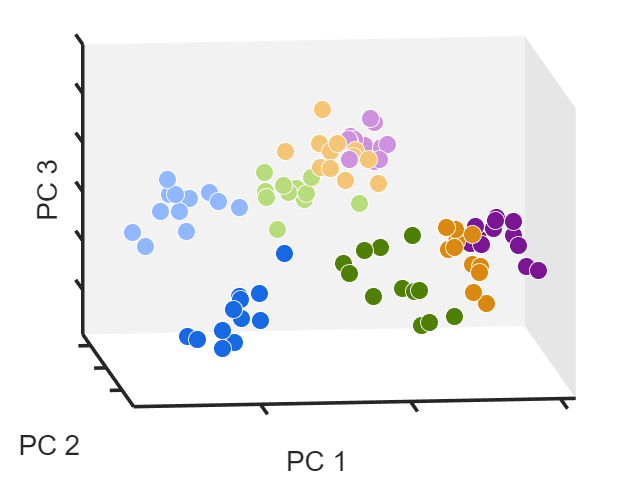

% Step 2 of PCA. Project single-trial, time-averaged responses onto the PCs
% (Figure 3C, 4E, 5E)


% For each trial, average the response during a given window that's
% palatability-relevant
average_window = 65:95; % 1.5s to 4.5 s

% Average response during 1-4 sec post stimulus cell x trials
S_bin_mean = squeeze(mean(S_aligned_df(:,:, average_window), 3));
N_bin_mean = squeeze(mean(N_aligned_df(:,:, average_window), 3));
C_bin_mean = squeeze(mean(C_aligned_df(:,:, average_window), 3));
Q_bin_mean = squeeze(mean(Q_aligned_df(:,:, average_window), 3));

% Max val normalization
S_bin_mean = S_bin_mean ./ max_val;
N_bin_mean = N_bin_mean ./ max_val;
C_bin_mean = C_bin_mean ./ max_val;
Q_bin_mean = Q_bin_mean ./ max_val;

S_bin_mean_nostim = S_bin_mean(cell_list_for_analysis, nostim_trials, :);
N_bin_mean_nostim = N_bin_mean(cell_list_for_analysis, nostim_trials, :);
C_bin_mean_nostim = C_bin_mean(cell_list_for_analysis, nostim_trials, :);
Q_bin_mean_nostim = Q_bin_mean(cell_list_for_analysis, nostim_trials, :);

S_bin_mean_stim = S_bin_mean(cell_list_for_analysis, stim_trials, :);
N_bin_mean_stim = N_bin_mean(cell_list_for_analysis, stim_trials, :);
C_bin_mean_stim = C_bin_mean(cell_list_for_analysis, stim_trials, :);
Q_bin_mean_stim = Q_bin_mean(cell_list_for_analysis, stim_trials, :);


bin_mean_design_mat = cat(1,S_bin_mean_nostim', ...
    N_bin_mean_nostim', ...
    C_bin_mean_nostim', ...
    Q_bin_mean_nostim', ...
    S_bin_mean_stim', ...
    N_bin_mean_stim', ...
    C_bin_mean_stim', ...
    Q_bin_mean_stim');


% Projecting trial-preserved data onto PCs defined using time-preserved data.
bin_mean_mat_projected = bin_mean_design_mat * coeff(:, 1:6);


trial_type_label = repelem(1:8, trial_num);

% Plot the top 3 principal components
figure;
hold on;
for i = 1:8
    % Select data for the i-th class (251 observations per class)
    trial_type = (trial_type_label == i);
    class_data = bin_mean_mat_projected(trial_type, 1:3);
    
    %Plot the data points for the i-th class with specified color
    scatter3(class_data(:, 1), class_data(:, 2), class_data(:, 3), 100, ...
             'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', 'w', ...
             'DisplayName', sprintf('Class %d', i));
end

%Label the axes
xlabel('PC 1');
ylabel('PC 2');
zlabel('PC 3');

set(gca, "XTickLabel", []);
set(gca, "YTickLabel", []);
set(gca, "ZTickLabel", []);

grid off;
box of;
axis padded manual;
set(gca, "FontSize", 14, "FontName", "Arial", "LineWidth", 2, "GridLineWidth", 0.8);

view([173.43 14.07]); % For phasic 4T

xlims = xlim;
ylims = ylim;
zlims = zlim;
add3DBoxShading(xlims, ylims, zlims);


hold off;

% Step 3 of PCA. Calculate projection on to te attribute-axis
% (Figure 3D-G, 4F-I, 5F-I, 6GJM, 7E-J)


% Two methods for caculating attribute axes:
% PA_project (palatable-aversive) uses palatable and centroids(for palatability exp).
% SQ_project (sucrose-quinine) uses centroids of end-range tastants (for mixture and sucrose exp).
[axis_scores, axis_orth, theta_axes_deg, axis_nostim, axis_stim] = PA_project(bin_mean_mat_projected, trial_type_label);
% [axis_scores, axis_orth, theta_axes_deg, axis_nostim, axis_stim] = SQ_project(bin_mean_mat_projected, trial_type_label);

% Calculate dispersion ratio
orth_ratio = mean(axis_orth(49:96)) / mean(axis_orth(1:48));

% Permutation test for coding axis projection (PA)
rng(1);

nperms = 1000;
axis_scores_perm = zeros(length(trial_type_label), nperms);
theta_perm = zeros(1, nperms);
orth_ratio_perm = zeros(1, nperms);

for i = 1:nperms
    trial_type_label_perm = permute_labels(trial_type_label);
    [scores, orth, angle] = PA_project(bin_mean_mat_projected, trial_type_label_perm);
    axis_scores_perm(:, i) = scores;
    theta_perm(i) = angle;
    orth_ratio_perm(i) = mean(orth(49:96)) / mean(orth(1:48));
end

figure;
dr_ratio_perm = dynamic_range_ratio(axis_scores_perm);
dr_ratio = dynamic_range_ratio(axis_scores)

dr_ratio = 1.5519

p_val_dr = mean(abs(dr_ratio_perm-1) >= abs(dr_ratio-1))

p_val_dr = 0

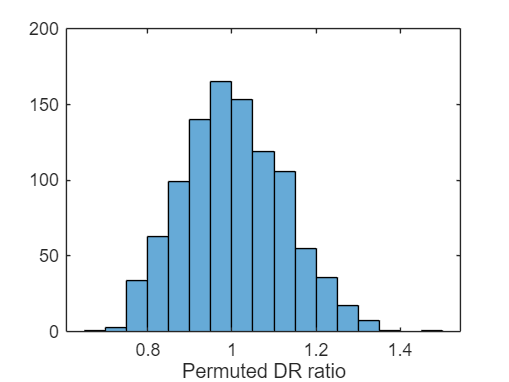

histogram(dr_ratio_perm)
xlabel('Permuted DR ratio')


theta_axes_deg

theta_axes_deg = 26.8146

p_val_theta = mean(theta_perm >= theta_axes_deg)

p_val_theta = 0.0990

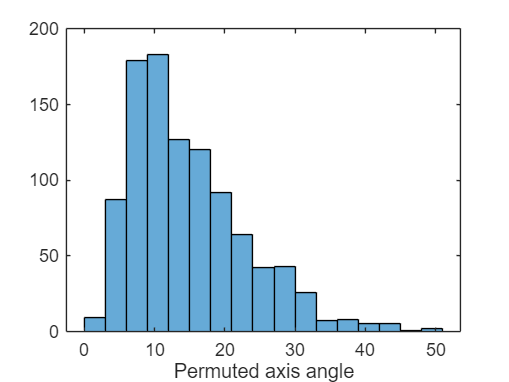

histogram(theta_perm)
xlabel('Permuted axis angle')


orth_ratio

orth_ratio = 1.1225

p_val_orth = mean(abs(orth_ratio_perm-1) >= abs(orth_ratio-1))

p_val_orth = 0.0740

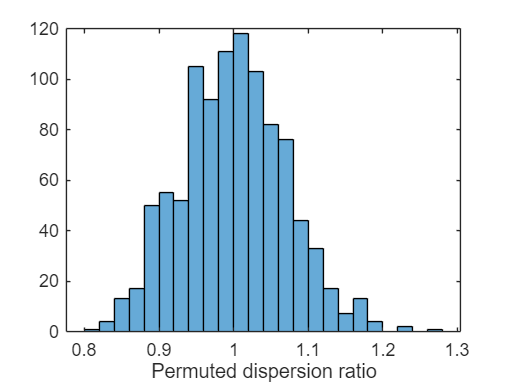

histogram(orth_ratio_perm)
xlabel('Permuted dispersion ratio')

% I used a one-sided p-value here because the null distribution relects
% variation in the estimation of the angle caused by noise. If
% neuromodulation produces addtional rotation, the total rotation will most likelu be
% on the right tail of the distribution.

% Procrustes analysis
centroids_nostim = zeros(4, 6);
for i = 1:4
    centroids_nostim(i, :) = mean(bin_mean_mat_projected(trial_type_label == i, :), 1);
end

centroids_stim = zeros(4, 6);
for i = 5:8
    centroids_stim(i-4, :) = mean(bin_mean_mat_projected(trial_type_label == i, :), 1);
end

[d, centroids_procrustes] = procrustes(centroids_nostim(:, 1:3), centroids_stim(:, 1:3));

procrustes_compare_mat = [centroids_nostim(:, 1:3); centroids_procrustes(:, 1:3)];

% Step 1 of Modulation type analysis. Classify neurons by modulation type.
% The paper used all stimulus-discriminative neurons (D_and_R).


% Use time bin-averaged tuning profiles
data_mod_type = cat(2, combined_binned_sig_nostim, combined_binned_sig_stim);

data_mod_type_mean = mean(data_mod_type(:,:,3:9), 3); % Cell x trials
ncells = size(data_mod_type, 1);

mod_type = cell(ncells, 1);

AFs = nan(ncells, 1);   % additive factors (alpha)
MFs   = nan(ncells, 1);   % multiplicative factors (1 + beta)

warning('off','stats:nlinfit:IterationLimitExceeded');
warning('off','stats:nlinfit:IllConditionedJacobian');

for cell_id = 1:ncells

    cell_responses = squeeze(data_mod_type_mean(cell_id,:))';
    taste_labels = [repelem(1:4, 12), repelem(1:4, 12)]';
    stim_labels  = repelem([0 1], 48)';

    data_tab = table(cell_responses, categorical(taste_labels), ...
        categorical(stim_labels), ...
        'VariableNames', {'Response', 'Taste', 'Stim'});

    %% --- Linear models ---
    % Null: taste only
    mdl0 = fitlm(data_tab, "Response ~ Taste");

    % Interaction: taste × stim (Flexible modulation)
    mdl1 = fitlm(data_tab, "Response ~ Taste * Stim");

    %% --- Combined nonlinear model (Scale-shift) ---
    X = [double(taste_labels), double(stim_labels)];
    y = cell_responses;

    comb_fun = @(p, X) ...
        p(X(:,1))' .* (1 + p(5) .* X(:,2)) + p(6) .* X(:,2);

    init = [ ...
        mean(y(taste_labels==1)), ...
        mean(y(taste_labels==2)), ...
        mean(y(taste_labels==3)), ...
        mean(y(taste_labels==4)), ...
        0, ...   % beta (Mult. factor-1)
        0  ...   % alpha (Add. factor)
        ];

    mdl3 = fitnlm(X, y, comb_fun, init);

    %% --- Extract parameters ---
    MF_hat   = 1 + mdl3.Coefficients.Estimate(5);
    AF_hat = mdl3.Coefficients.Estimate(6);

    %% --- Model comparison ---
    ic_null = mdl0.ModelCriterion.AIC;
    ic_int  = mdl1.ModelCriterion.AIC;
    ic_comb = mdl3.ModelCriterion.AIC;

    % ---- Disqualify combined model if parameters are extreme ----
    if MF_hat > 10 || MF_hat < 0.1 || abs(AF_hat) > 10
        ic_comb = Inf;
    end

    thresh = 2;
    ics = [ic_null, ic_comb, ic_int];

    [ic_best, idx_best] = min(ics);

    %% --- Model selection ---
    if (ic_null - ic_best) <= thresh
        mod_type{cell_id} = 'null';

    elseif (ic_comb - ic_best) <= thresh
        mod_type{cell_id} = 'scale-shift';

        % Store parameters only if combined model wins
        MFs(cell_id)   = MF_hat;
        AFs(cell_id) = AF_hat;

    else
        mod_type{cell_id} = 'flexible';

    end

end

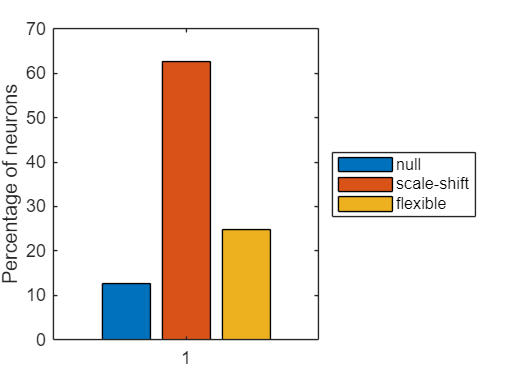

% Step 2 of Modulation type analysis. Quantifications.
% (Figure 6, S8)


% Visulize the fraction of each modulation type
mod_type_list = {'null', 'scale-shift', 'flexible'};
mod_type_counts = zeros(1, 3);

for type = 1:numel(mod_type_list)
    mod_type_counts(type) = sum(strcmp(mod_type, mod_type_list{type}));
end

fractions = 100* (mod_type_counts ./ ncells); % fraction of population

%stacked graph of prevalence
figure;
bar(1, fractions, 'grouped');
ylabel('Percentage of neurons');
legend(mod_type_list, 'Location','eastoutside');

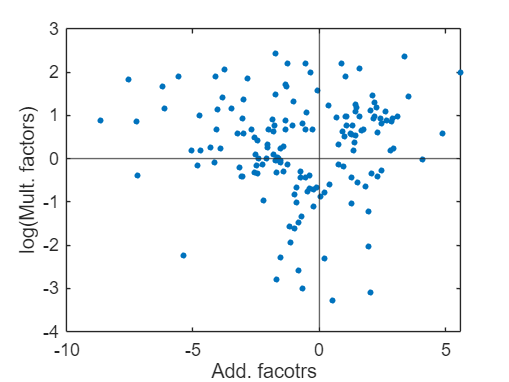


% Log transform multiplicative factors
log_MFs = log2(MFs);

% Plot additive against multiplicative factors
plot(AFs, log_MFs, ".", 'MarkerSize', 10);
xline(0);
yline(0);

xlabel('Add. facotrs');
ylabel('log(Mult. factors)');

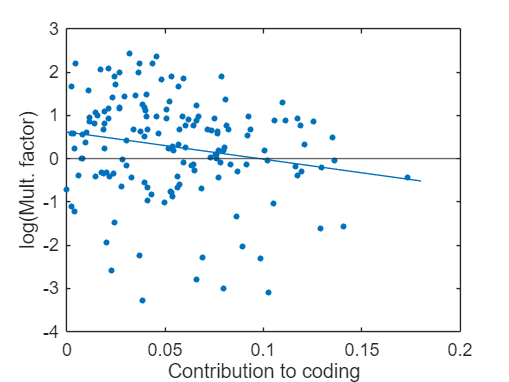


% Correlate neuronal contributions to coding axis with multiplicative factors
axis_weights = coeff(:, 1:6) * axis_nostim';
abs_weight = abs(axis_weights);

figure;
plot(abs_weight, log_MFs, ".", 'MarkerSize', 10)
hold on
yline(0)
xlabel('Contribution to coding');
ylabel('log(Mult. factor)');
lsline


[rho, p_corr] = corr(abs_weight(~isnan(log_MFs)), log_MFs(~isnan(log_MFs)))

rho = -0.1954

p_corr = 0.0148